**PUNTO 4. Funciones de distancia bivariad**

En principio, se simulan 10 mil puntos aleatorios con distibución normal bivariante.

clearvars
n = 10000;

**Distancia 1**

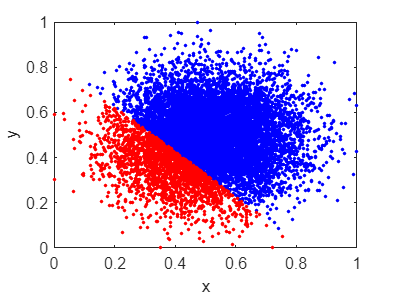

% Definir conjunto de reales aleatorios normales
R = randn(n,2);
x = round(R(:,1), 4);
y = round(R(:,2), 4);

% Estandarizar conjunto [0,1]
x = rescale(x,0,1);
y = rescale(y,0,1);

% Calcular la distancia condicional
d = zeros(n,1);
j = find(x ~= y);
d(j) = 2 - x(j) - y(j);

% Encontar percentil 80
p80 = prctile(d, 80);
posN = find(d <= p80);
posO = find(d > p80);

% Graficar
figure; cla;
plot(x(posN), y(posN), 'b.', x(posO), y(posO), 'r.')
xlabel('x'); ylabel('y')
axis normal

**Distancia 2**

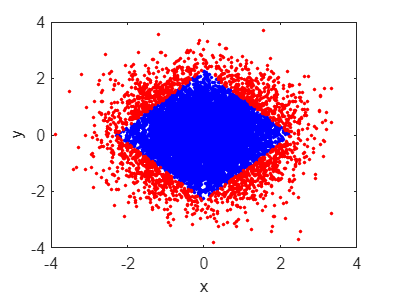

% Definir conjunto de reales aleatorios normales
x = randn(n,1);
y = randn(n,1);

% Calcular la distancia condicional
d = zeros(n,1);
j = find(x ~= y);
a = 0;
d(j) = abs(x+a) + abs(y+a);

% Encontar percentil 80
p80 = prctile(d, 80);
posN = find(d <= p80);
posO = find(d > p80);

% Graficar
figure;
plot(x(posN), y(posN), 'b.', x(posO), y(posO), 'r.')
xlabel('x'); ylabel('y')
axis normal

**Distancia 4**

% Definir conjunto de enteros aleatorios normales
clearvars
n = 10000

n = 10000

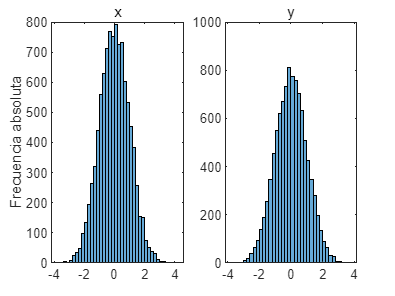

x = randn(n, 1);
y = randn(n, 1);

% Histogramas
figure; hold off;
subplot(1,2,1); histogram(x); subtitle('x');
ylabel('Frecuencia absoluta')
subplot(1,2,2); histogram(y); subtitle('y');


% Calcular la distancia condicional
d = zeros(n,1);
j = find(x ~= y);
d(j) = 1 + 1./(x + y);

% Encontar percentil 80
p80 = prctile(d, 80)

p80 = 2.3429

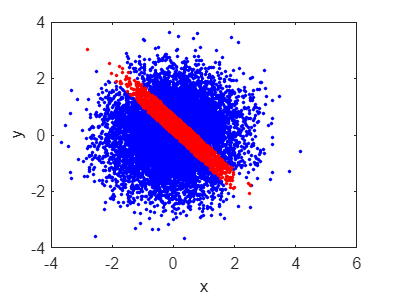

posN = find(d <= p80);
posO = find(d > p80);

% Graficar
figure;
plot(x(posN), y(posN), 'b.', x(posO), y(posO), 'r.')
xlabel('x'); ylabel('y')